clear all;
close all;
clc;


% Assuming Ts is 1e-4
Ts = 1e-3;
x = -10 * Ts:1e-4:10 * Ts

x =    -0.0100   -0.0099   -0.0098   -0.0097   -0.0096   -0.0095   -0.0094   -0.0093   -0.0092   -0.0091   -0.0090   -0.0089   -0.0088   -0.0087   -0.0086   -0.0085   -0.0084   -0.0083   -0.0082   -0.0081   -0.0080   -0.0079   -0.0078   -0.0077   -0.0076   -0.0075   -0.0074   -0.0073   -0.0072   -0.0071   -0.0070   -0.0069   -0.0068   -0.0067   -0.0066   -0.0065   -0.0064   -0.0063   -0.0062   -0.0061   -0.0060   -0.0059   -0.0058   -0.0057   -0.0056   -0.0055   -0.0054   -0.0053   -0.0052   -0.0051


y = sinc(x / Ts)

y =    -0.0000   -0.0099   -0.0191   -0.0265   -0.0315   -0.0335   -0.0322   -0.0277   -0.0203   -0.0108    0.0000    0.0111    0.0213    0.0296    0.0352    0.0374    0.0360    0.0310    0.0228    0.0121   -0.0000   -0.0125   -0.0240   -0.0334   -0.0398   -0.0424   -0.0409   -0.0353   -0.0260   -0.0139    0.0000    0.0143    0.0275    0.0384    0.0459    0.0490    0.0473    0.0409    0.0302    0.0161   -0.0000   -0.0167   -0.0323   -0.0452   -0.0541   -0.0579   -0.0561   -0.0486   -0.0360   -0.0193


plot(x, y)
hold on
grid on;
x = -9 * Ts:1e-5: 11*Ts

x =    -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0090   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0089   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0088   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0087   -0.0086   -0.0086   -0.0086   -0.0086   -0.0086   -0.0086   -0.0086   -0.0086   -0.0086   -0.0086   -0.0085   -0.0085   -0.0085   -0.0085


y = sinc((x - Ts) / Ts)

y =     0.0000   -0.0010   -0.0020   -0.0030   -0.0040   -0.0050   -0.0060   -0.0070   -0.0080   -0.0090   -0.0099   -0.0109   -0.0119   -0.0128   -0.0137   -0.0147   -0.0156   -0.0165   -0.0174   -0.0182   -0.0191   -0.0199   -0.0207   -0.0215   -0.0223   -0.0231   -0.0238   -0.0245   -0.0252   -0.0259   -0.0265   -0.0272   -0.0278   -0.0283   -0.0289   -0.0294   -0.0299   -0.0303   -0.0308   -0.0312   -0.0315   -0.0319   -0.0322   -0.0325   -0.0327   -0.0329   -0.0331   -0.0333   -0.0334   -0.0335


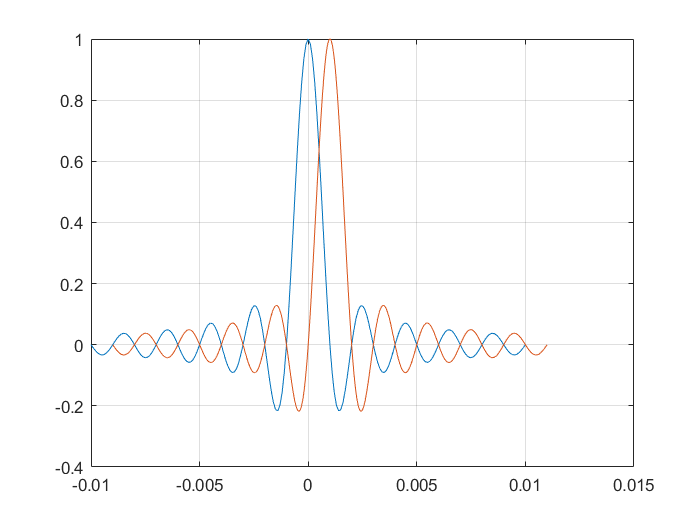

plot(x, y)

hold off;

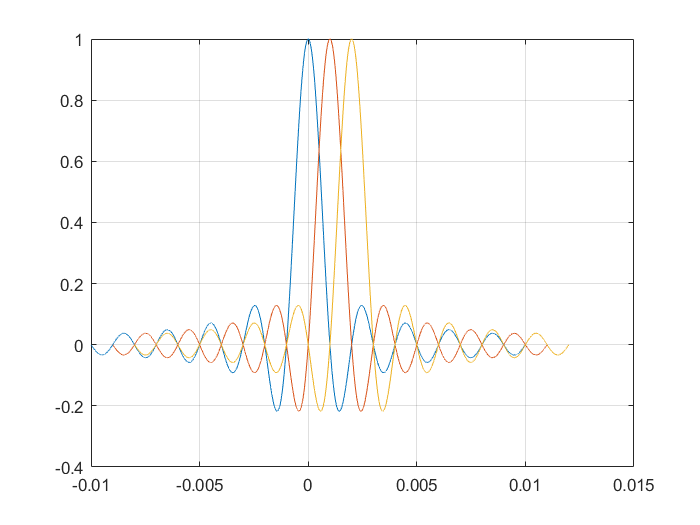

for i = 1:3
    x = (-10 + i - 1) * Ts:1e-6:(10 + i -1) * Ts;
    y = sinc((x-(i-1)*Ts) / Ts);
    plot(x, y)
    hold on
    grid on;
end

clear all;
close all;
clc;


N = 100; % 100 data points
fs = 1000; % 1kHz sampling frequency
T = 1/fs; % sample period
f = 200; % signal frequency in Hz
n = 0:N-1; % discrete time vector
x = cos(2*pi*f*n*T); %signal definition
%plot the signal against time
y = stem(n*T,x);
sample_data = y.YData
title('200Hz cosine')
xlabel('Time')
ylabel('x(nT)')

plot(n*T,x);
signal_recover_final = zeros(1,20001);
for  i = 1:100
    x = (-10 + i - 1) * T:1e-6:(10 + i -1) * T;
    sinc_temp = sinc(x / T);
    signal_recover_temp = sample_data(i) * sinc_temp;
    signal_recover_final = signal_recover_final + signal_recover_temp;
end
x = -10 * T:1e-6:10 * T
plot(x, signal_recover_final);

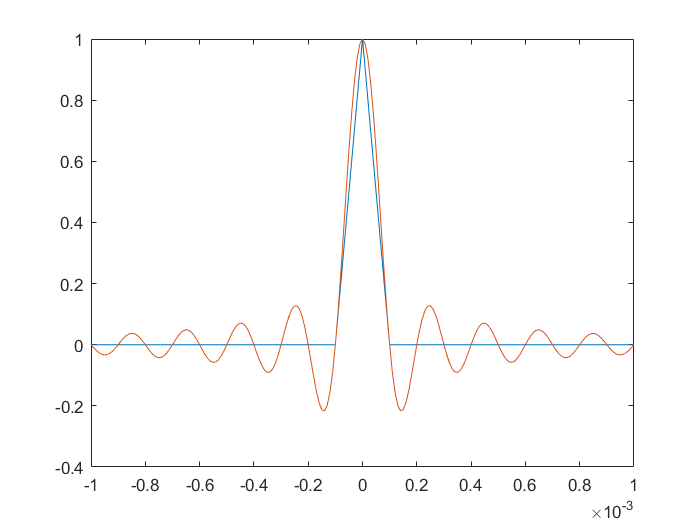

% Case where sampling rate for original signal and sinc are the same.
% In this case we may even not be able to plot a 'right' sinc function.

clear all;
close all;
clc;

% x =  -10 * 1e-4:1e-4:10 * 1e-4;
% y = sinc(x / 1e-4);
% plot(x,y);
% hold on;
% x =  -10 * 1e-4:1e-5:10 * 1e-4;
% y = sinc(x / 1e-4);
% plot(x,y);


M = zeros(1021, 1000);
sinc_result= zeros(1021, 1000);
for i = 1:1000
    x = (-10 + i - 1) * 1e-4:1e-4:(10 + i - 1) * 1e-4;
    M([i:i+20], i) = x;
    sinc_result([i:i+20], i) = sinc((M([i:i+20], i)- (i-1) * 1e-4) / 1e-4);
    plot(M([i:i+20], i), sinc_result([i:i+20], i));
    hold on;
    grid on;
end
hold off;

N = 1000; % 1000 data points
fs = 10000; % 10kHz sampling frequency
T = 1/fs; % sample period
f = 200; % signal frequency in Hz
n = 0:N-1; % discrete time vector
x = cos(2*pi*f*n*T); %signal definition
%plot the signal against time
y = stem(n*T,x);
sample_data = y.YData
title('200Hz cosine')
xlabel('Time')
ylabel('x(nT)')

plot(n*T,x);

signal_recover_times_samples = sample_data .* sinc_result;
signal_recover_final = sum(signal_recover_times_samples, 2);
x = -10 * T:1e-4:0.1 + 10 * T
plot(x, signal_recover_final)

% If we increase the sampling frequency for sinc?
% Here sampling sinc at 100kHz
clear all;
close all;
clc;

M = zeros(10201, 1000);
sinc_result= zeros(10201, 1000);
for i = 1:1000
    x = (-10 + i - 1) * 1e-4:1e-5:(10 + i - 1) * 1e-4;
    M(1+(i-1)*10:1+(i-1)*10+200, i) = x;
    sinc_result([1+(i-1)*10:1+(i-1)*10+200], i) = sinc( (M(1+(i-1)*10:1+(i-1)*10+200, i)- (i-1) * 1e-4) / 1e-4);
%     plot(M([i:i+200], i), sinc_result([i:i+200], i));
%     hold on;
%     grid on;
end
% hold off;

N = 1000; % 1000 data points
fs = 10000; % 10kHz sampling frequency
T = 1/fs; % sample period
f = 200; % signal frequency in Hz
n = 0:N-1; % discrete time vector
x = cos(2*pi*f*n*T); %signal definition
%plot the signal against time
y = stem(n*T,x);
sample_data = y.YData

sample_data =     1.0000    0.9921    0.9686    0.9298    0.8763    0.8090    0.7290    0.6374    0.5358    0.4258    0.3090    0.1874    0.0628   -0.0628   -0.1874   -0.3090   -0.4258   -0.5358   -0.6374   -0.7290   -0.8090   -0.8763   -0.9298   -0.9686   -0.9921   -1.0000   -0.9921   -0.9686   -0.9298   -0.8763   -0.8090   -0.7290   -0.6374   -0.5358   -0.4258   -0.3090   -0.1874   -0.0628    0.0628    0.1874    0.3090    0.4258    0.5358    0.6374    0.7290    0.8090    0.8763    0.9298    0.9686    0.9921


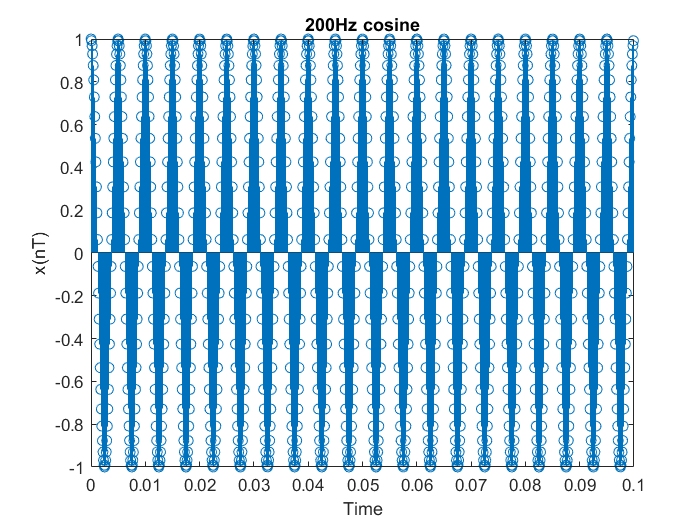

title('200Hz cosine')
xlabel('Time')
ylabel('x(nT)')

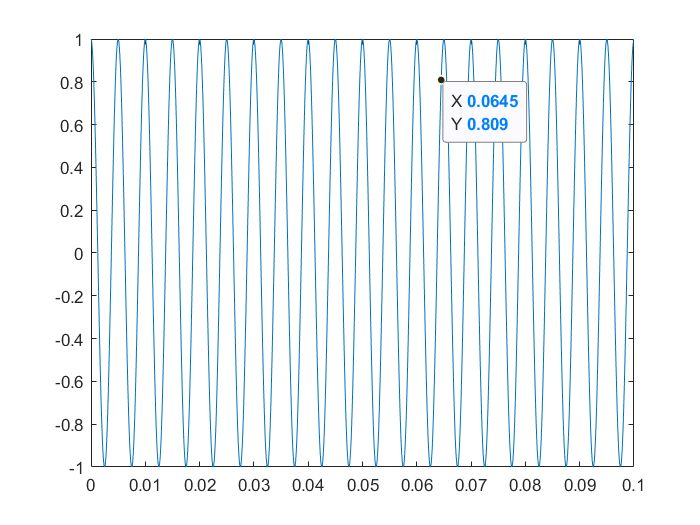


plot(n*T,x);


signal_recover_times_samples = sample_data .* sinc_result;
signal_recover_final = sum(signal_recover_times_samples, 2);
x = -10 * T:1e-5:0.1 + 10 * T

x =    -1.0000   -0.9900   -0.9800   -0.9700   -0.9600   -0.9500   -0.9400   -0.9300   -0.9200   -0.9100   -0.9000   -0.8900   -0.8800   -0.8700   -0.8600   -0.8500   -0.8400   -0.8300   -0.8200   -0.8100   -0.8000   -0.7900   -0.7800   -0.7700   -0.7600   -0.7500   -0.7400   -0.7300   -0.7200   -0.7100   -0.7000   -0.6900   -0.6800   -0.6700   -0.6600   -0.6500   -0.6400   -0.6300   -0.6200   -0.6100   -0.6000   -0.5900   -0.5800   -0.5700   -0.5600   -0.5500   -0.5400   -0.5300   -0.5200   -0.5100


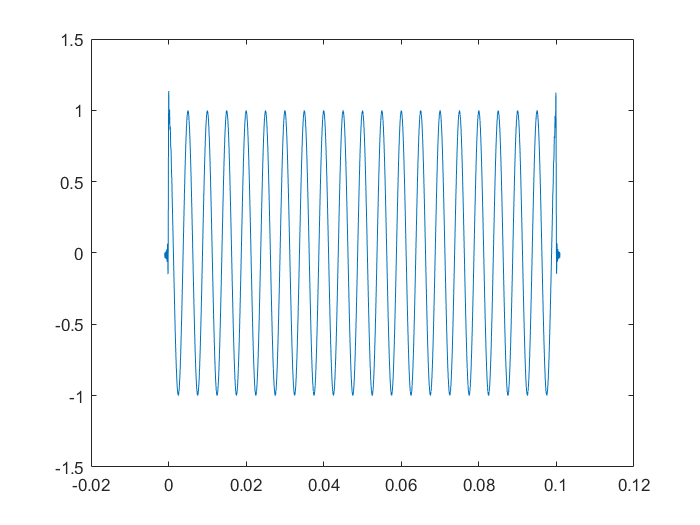

plot(x, signal_recover_final)


% At the beginning and end of the recovering curve, the recovering result
% was not satisfactory, I think this was due to the reason that both at the
% beginning and end of the curve, there was not enough sinc function value
% to help build the recover signal (because we tuncated the sinc function 
% within +-10T).